## IDDTFT/IFFT

### A)

y = [];

Sum = 0;

for t1=tf

    for f1=f_values

        Sum = Sum + X(f1)*exp(1i*2*pi*(f1-1)*(t1-1));

    end

    y(end+1) = Sum;

    Sum = 0;

end

% x = dot(X, exp(1i*2*pi*(f-1)*tf))

### B)

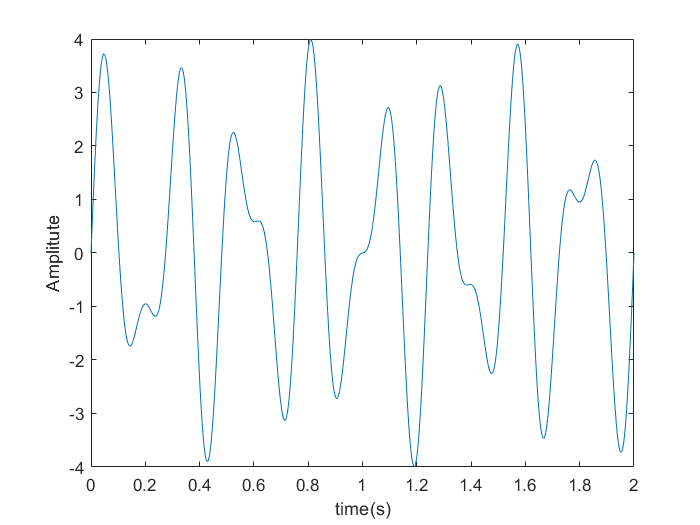

clear all

x = struct2array(load('signal.mat'));

tmin = 0;
tmax = 2;
sampling_rate = (length(x)-1) / (tmax-tmin);
npts = (tmax-tmin)*sampling_rate + 1;
t_values = tmin:(1/sampling_rate):tmax;
f_values = 1:npts;
tf = (0:npts-1)/npts;

plot(t_values, x)
xlabel('time(s)')
ylabel('Amplitute')

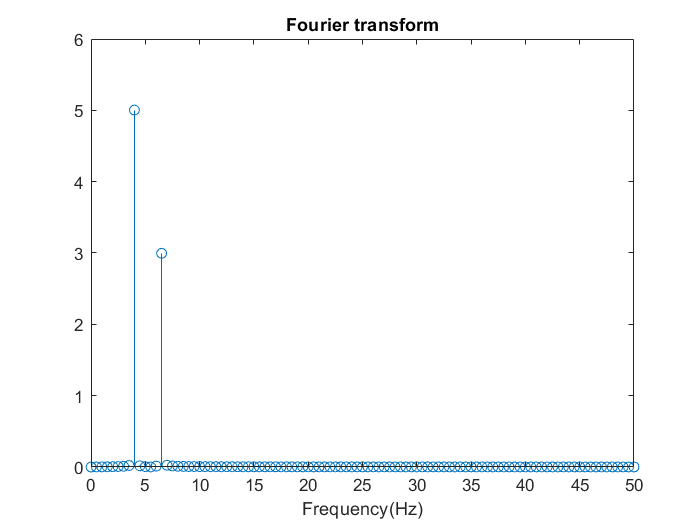


X = [];
for f=f_values
    X(end+1) = dot(x, exp(-1i*2*pi*(f-1)*tf));
end

figure
f_shifted_values = linspace(-sampling_rate/2, sampling_rate/2, npts);
stem(f_shifted_values, 2*fftshift(abs(X))/sampling_rate)
title('Fourier transform')
xlabel('Frequency(Hz)')
xlim([0 50])

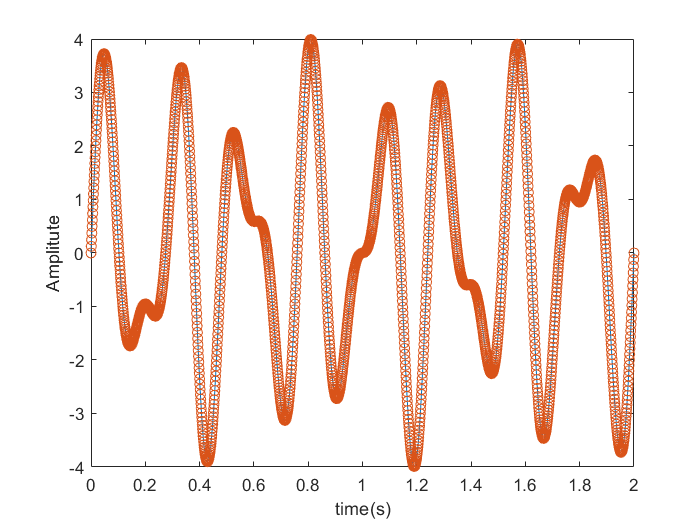


y = [];

Sum = 0;
for t1=tf
    for f1=f_values
        Sum = Sum + X(f1)*exp(1i*2*pi*(f1-1)*(t1-1));
    end
    y(end+1) = Sum;
    Sum = 0;
end

plot(t_values, x)
xlabel('time(s)')
ylabel('Amplitute')
hold on
scatter(t_values, 0.5*real(y)/sampling_rate)
hold off

### C)

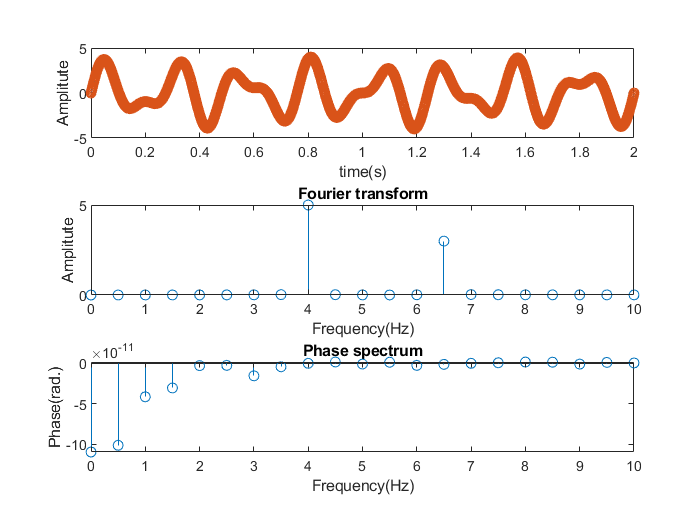

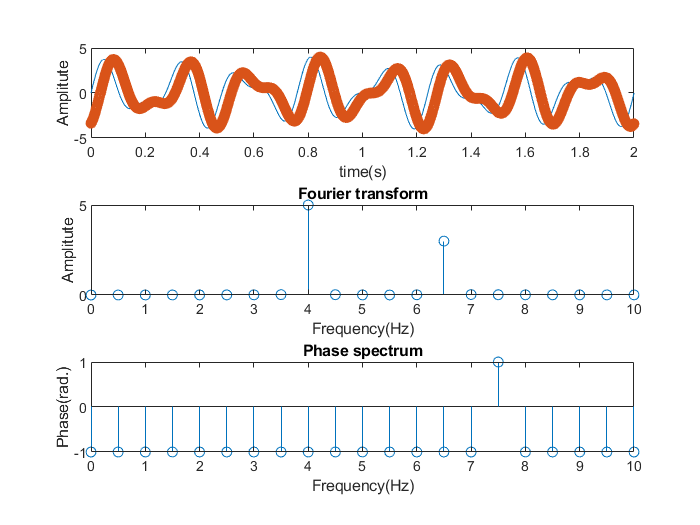

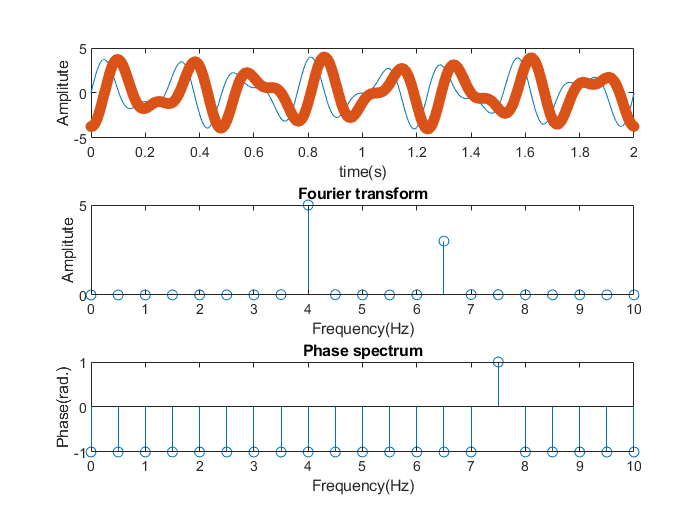

alpha = [0 35 50];
tf1 = (alpha(1):npts+alpha(1)-1) / npts;
tf2 = (alpha(2):npts+alpha(2)-1) / npts;
tf3 = (alpha(3):npts+alpha(3)-1) / npts;
new_tf = [tf1; tf2; tf3];

for i=(1:length(alpha))
    curr_X = [];
    for f=f_values
        curr_X(end+1) = dot(x, exp(-1i*2*pi*(f-1)*new_tf(i, :)));
    end    
    
    curr_y = [];
    
    Sum = 0;
    for t1=new_tf(1, :)
        for f1=f_values
            Sum = Sum + curr_X(f1)*exp(1i*2*pi*(f1-1)*(t1-1));
        end
        curr_y(end+1) = Sum;
        Sum = 0;
    end    
    
    figure
    subplot(3, 1, 1)
    
    plot(t_values, x)
    xlabel('time(s)')
    ylabel('Amplitute') 
    
    hold on
    scatter(t_values, 0.5*real(curr_y)/sampling_rate)
    hold off
    
    subplot(3, 1, 2)
    
    f_shifted_values = linspace(-sampling_rate/2, sampling_rate/2, npts);
    stem(f_shifted_values, 2*fftshift(abs(curr_X))/sampling_rate)
    title('Fourier transform')
    xlabel('Frequency(Hz)')
    ylabel('Amplitute') 
    xlim([0 10])    
    
    subplot(3, 1, 3)
    tol = 1e-6;
    curr_y(abs(curr_y) < tol) = 0;
    
    theta = angle(curr_y);
    
    stem(f_shifted_values,theta/pi)
    xlim([0 10])  
    title('Phase spectrum')
    xlabel 'Frequency(Hz)'
    ylabel 'Phase(rad.)'
end

It changes phase spetrum, but it doesn't change fourier transform and fourier transform is not affected buy changing alpha.